# PHYS 4030 Homework 3: Discrimination in Prices

**Name: **Johannes Irnawan

**ID:** 215 010 960

The goal of this lab is to determine whether the given fast food restaurants are using discriminatory pricing.

# Loading and Cleaning the Data

% Clearing up the memory:
clear; clf;
% Loading the data set:
data_table = readtable('discrim.csv','ReadVariableNames',true);
% Cleaning up the data:
data_clean = CleanMyTable(data_table,height(data_table)/2);
% Show the first 8 rows of the cleaned data:
head(data_clean)

ans = 8×24 table
    psoda    pfries    pentree    wagest    nmgrs    nregs    hrsopen    emp     compown    chain    density     crmrte     state    prpblck      prppov     prpncar      hseval      nstores    income    county    NJ    BK    KFC    RR
    _____    ______    _______    ______    _____    _____    _______    ____    _______    _____    _______    ________    ____

We are trying to prove the discriminatory pricing used by fast food restaurants. To do this, we are gonna divide the data into a two categories:

- Prices (Soda, Fries, Entree)

- Discriminatory Population Category (Black fraction, Wages, No Car fraction)

% Putting Prices and Discriminatory Category:
Price.Soda = data_clean.psoda;
Price.Fries = data_clean.pfries;
Price.Entree = data_clean.pentree;
Disc.prpblck = data_clean.prpblck;
Disc.Wages = data_clean.wagest;
Disc.prpncar = data_clean.prpncar;

Our price category:

head(struct2table(Price))

ans = 8×3 table
    Soda    Fries    Entree
    ____    _____    ______

    1.12    1.06      1.02 
    1.06    0.91      0.95 
    1.06    0.91      0.98 
    1.12    1.02      1.06 
    1.06    0.95      1.01 
    1.17    0.95      0.95 
    1.17    1.02      1.06 
    1.17    1.12      1.02 


Our discriminatory category:

head(struct2table(Disc))

ans = 8×3 table
    prpblck     Wages    prpncar 
    ________    _____    ________

     0.17115    4.25     0.078843
     0.17115    4.75     0.078843
     0.04736    4.25      0.26943
    0.052839       5      0.13669
    0.059133    4.25      0.11513
    0.018677    4.65     0.050185
    0.004906     4.5     0.082711
     0.92106    4.25      0.39195


Before we start, we are going to normalize the data set:

% Normalize:
norm_val = struct2array(Price);
norm_val = (norm_val - mean(norm_val))./std(norm_val);
Price.Soda = norm_val(:,1);
Price.Fries = norm_val(:,2);
Price.Entree = norm_val(:,3);
norm_val = struct2array(Disc);
norm_val = (norm_val - mean(norm_val))./std(norm_val);
Disc.prpblck = norm_val(:,1);
Disc.Wages = norm_val(:,2);
Disc.prpncar = norm_val(:,3);

We can plot the prices against each other and price against the discriminatory category.

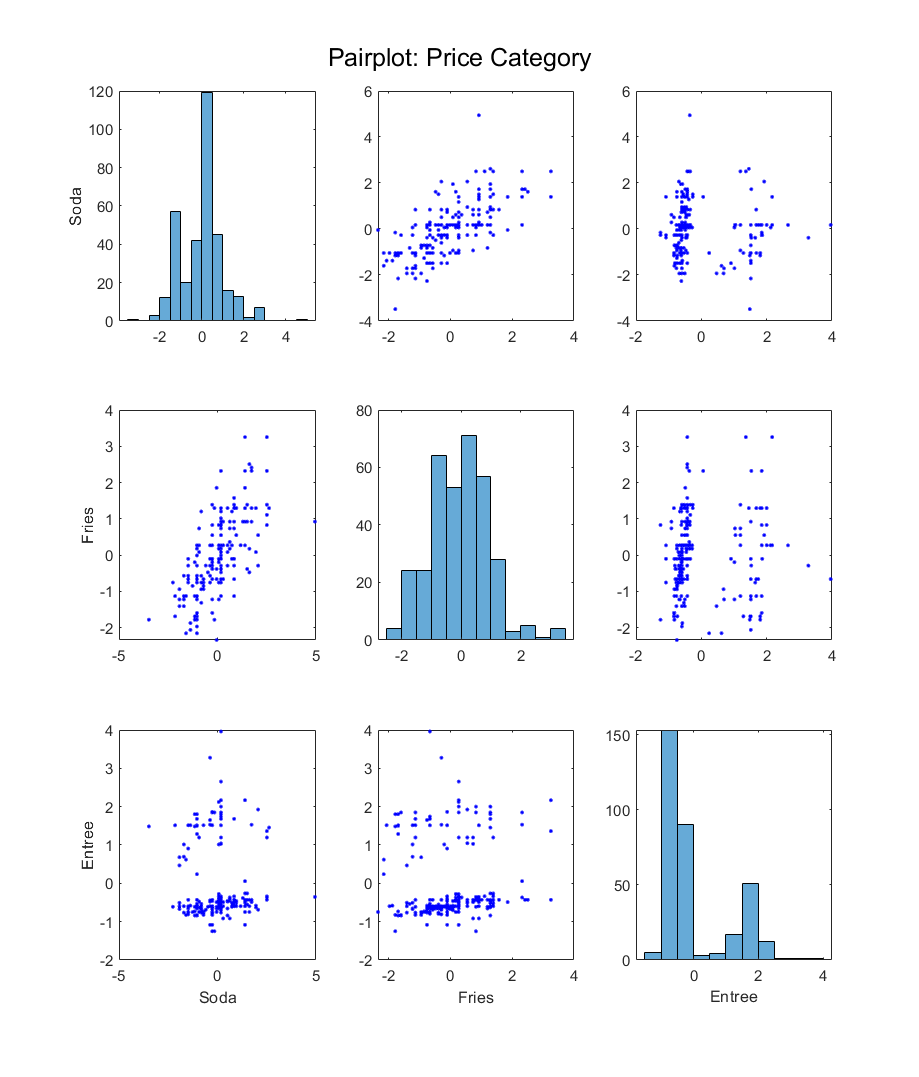

% Plotting prices vs prices:
clf; figure()
figure_1 = figure('Position', [100, 100, 1024, 1200]);
Price_array = struct2array(Price);
Price_label = ["Soda","Fries","Entree"];
for n = 1:length(Price_array(1,:))
    for m = 1:length(Price_array(1,:))
        subplot(3,3,(n - 1)*3 + m)
        if n == m
            histogram(Price_array(:,n))
        else
            plot(Price_array(:,m),Price_array(:,n),'b.')
        end
        if m == 1
            ylabel(Price_label(n))
        end
        if n == 3
            xlabel(Price_label(m))
        end
    end
end
sgtitle('Pairplot: Price Category')

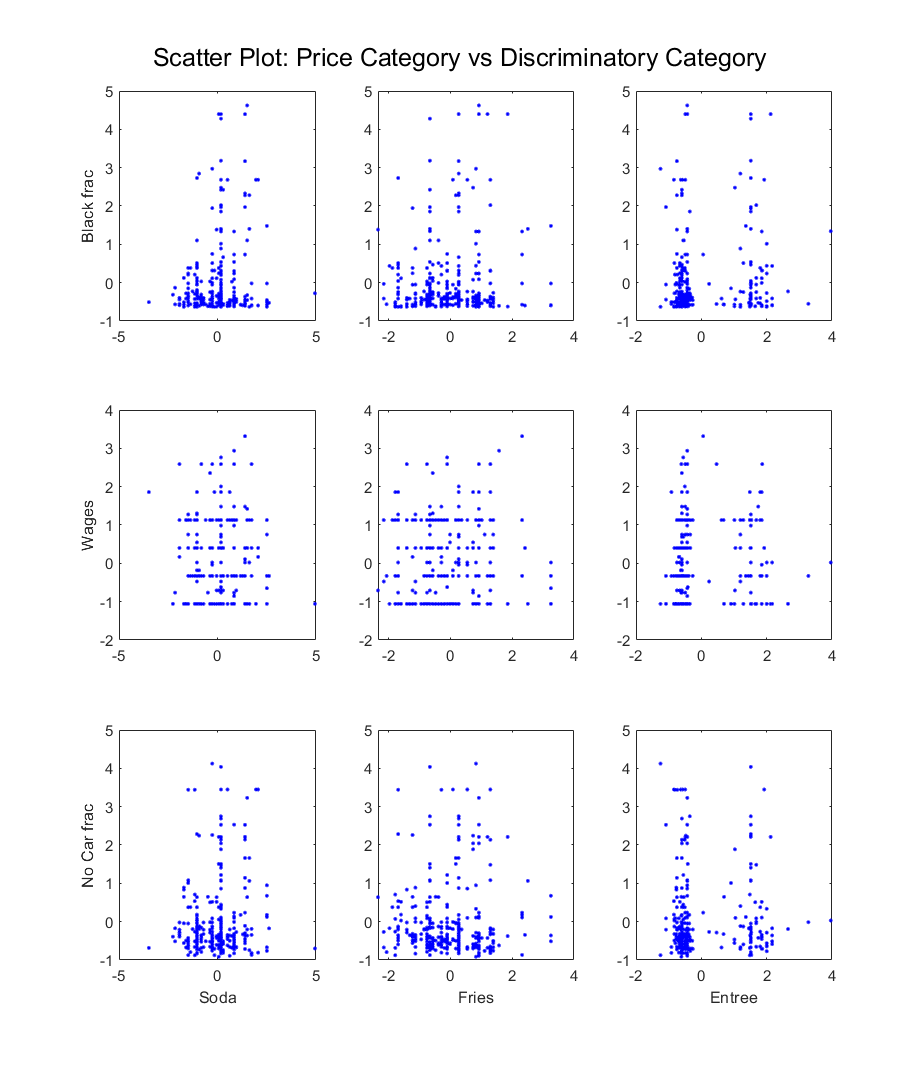

% Plotting prices vs discriminatory category:
clf; figure()
figure_1 = figure('Position', [100, 100, 1024, 1200]);
Disc_array = struct2array(Disc);
Disc_label = ["Black frac","Wages","No Car frac"];
for n = 1:length(Price_array(1,:))
    for m = 1:length(Price_array(1,:))
        subplot(3,3,(n - 1)*3 + m)
        plot(Price_array(:,m),Disc_array(:,n),'b.')
        if m == 1
            ylabel(Disc_label(n))
        end
        if n == 3
            xlabel(Price_label(m))
        end
    end
end
sgtitle('Scatter Plot: Price Category vs Discriminatory Category')

# Hypothesis

Looking at the previous graphs, it is fair to say that there does not seem to be any correlation between the discriminatory category chosen and the prices.

To prove this hypothesis, the Principal Component Analysis can be used. 

The idea is to use PCA on the price category and see if there is a correlation between the principal components and the discriminatory category. Using the linear regression, the linear fit should be relatively horizontal or vertical in order to prove that there is no discriminatory pricing.

# Constructing PCA on Discriminatory Category

The first step to constructing the PCA on the discriminatory category is to find the eigenvalues and the eigenvectors of the discriminatory category. However, since the data set is not square matrix, correlation coefficient can be used to find the correlation matrix and use it to find the eigenvalues and eigenvectors.

% Finding eigenvalues and eigenvectors of Disc. category:
Disc_corr = corrcoef(Disc_array);
[eigen.vector,eigen.value] = eig(Disc_corr);
% Sorting the eigenvalues and eigenvectors:
[val,n] = sort(diag(eigen.value));
eigen.value = eigen.value(n,n);
eigen.vector = eigen.vector(:,n);
struct2table(eigen)

ans = 3×2 table
                 vector                             value            
    ________________________________    _____________________________

    -0.68432     0.30839     0.66076    0.30954          0          0
     0.13279     0.94372    -0.30293          0    0.93592          0
     0.71699     0.11956     0.68675          0          0     1.7545


Now that the eigenvalues and the eigenvectors are in ascending order, the PCA can be computed using the eigenvectors. These eigenvectors are used as the projection matrix.

To get the transformed 2D Z matrix, the dot product of X and W can be taken, which are the discriminatory category and the eigenvectors respectively.

% Taking the dot product of X and W:
% For a dot product of a matrix and vector, MATLAB's built in command is
% NOT a good way to do dot product:
for k = 1:length(eigen.vector(1,:))
    for n = 1:length(Disc_array(:,1))
        for m = 1:length(Disc_array(1,:))
            comp(m) = Disc_array(n,m)*eigen.vector(m,k);
        end
        PComp(n,k) = sum(comp);
    end
end

The principal components should be uncorrelated. To see if they are uncorrelated, the principal components can be plotted against each other. The least correlated principal components will be used.

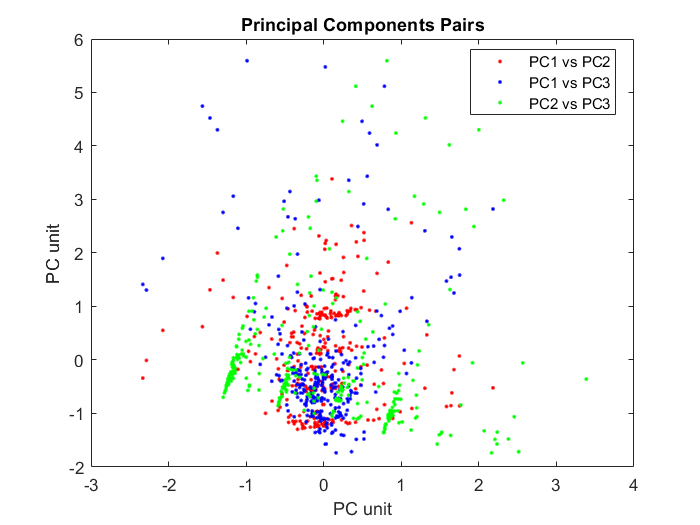

% Plotting the PC against each other to show uncorrelation:
clf; figure();
plot(PComp(:,1),PComp(:,2),'r.',PComp(:,1),PComp(:,3),'b.',...
    PComp(:,2),PComp(:,3),'g.');
title('Principal Components Pairs');
xlabel('PC unit'), ylabel('PC unit')
legend('PC1 vs PC2','PC1 vs PC3','PC2 vs PC3','Location','best')

# Using PCA to find Discriminatory Pricing

To find the discriminatory pricing, the pricing category and the principal components can be plotted. Linear regression can also be used and the mean crossval score can be calculated. This can be done separately, i.e. Price vs PC1 and Price vs PC3.

The first plot that will be plotted is the plot of Price vs PC1.

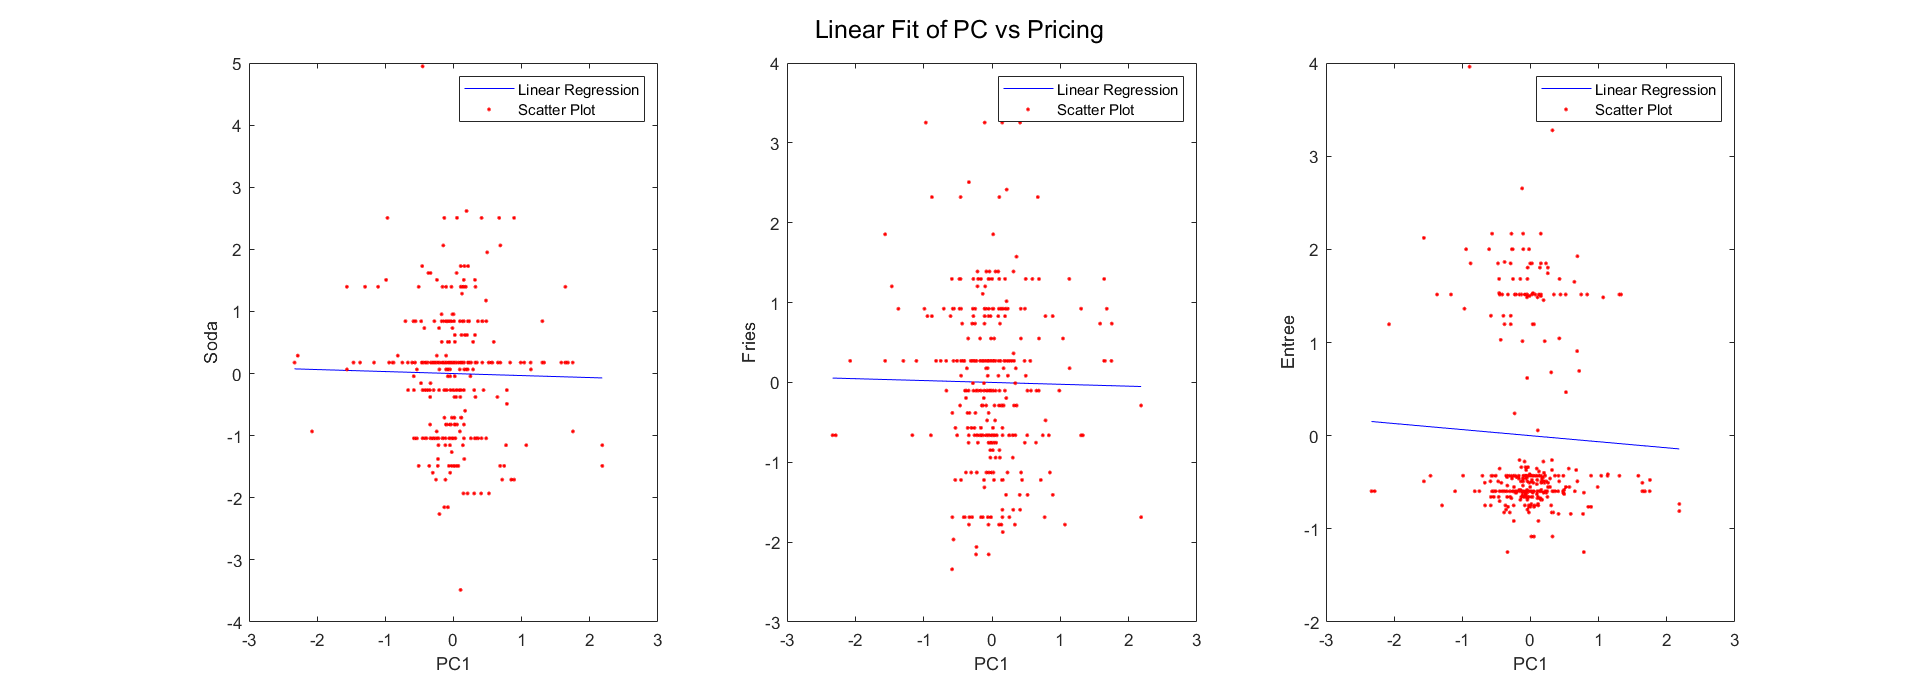

% Plotting PC1 against pricing:
clf; figure();
figure_1 = figure('Position', [100, 100, 2200, 800]);
X = [ones(length(Price_array(:,1)),1) PComp(:,1)];
for n = 1:length(Price_array(1,:))
    subplot(1,3,n)
    line_reg(n) = crossval('mse',X,Price_array(:,n),'Predfun',@regf);
    plot(PComp(:,1),PComp(:,1)*regress(PComp(:,1),Price_array(:,n)), ...
        'b-',PComp(:,1),Price_array(:,n),'r.')
    legend('Linear Regression','Scatter Plot')
    xlabel('PC1'), ylabel(Price_label(n))
end
sgtitle('Linear Fit of PC vs Pricing')

fprintf('The mean crossval scores are %f, %f, and %f.', ...
    line_reg)

The mean crossval scores are 1.002880, 1.003885, and 0.999523.

The second plot that can be compared is Price vs PC2.

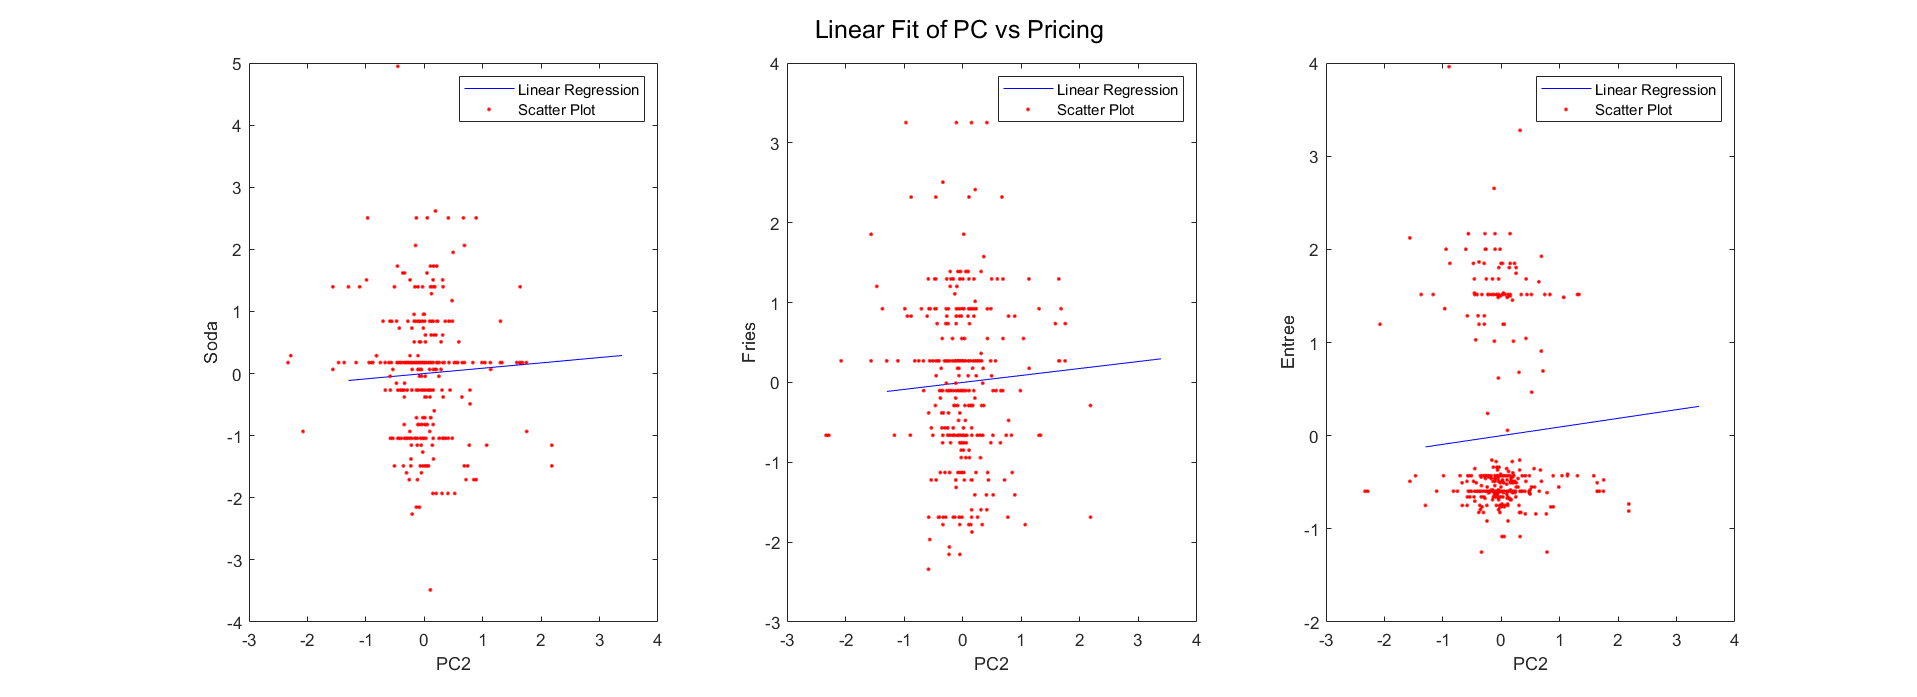

% Plotting PC2 against pricing:
clf; figure();
figure_1 = figure('Position', [100, 100, 2200, 800]);
X = [ones(length(Price_array(:,1)),1) PComp(:,2)];
for n = 1:length(Price_array(1,:))
    subplot(1,3,n)
    line_reg(n) = crossval('mse',X,Price_array(:,n),'Predfun',@regf);
    plot(PComp(:,2),PComp(:,2)*regress(PComp(:,2),Price_array(:,n)), ...
        'b-',PComp(:,1),Price_array(:,n),'r.')
    legend('Linear Regression','Scatter Plot')
    xlabel('PC2'), ylabel(Price_label(n))
end
sgtitle('Linear Fit of PC vs Pricing')

fprintf('The mean crossval scores are %f, %f, and %f.', ...
    line_reg)

The mean crossval scores are 1.004800, 1.005508, and 0.995574.

The third plot that can be compared is Price vs PC3.

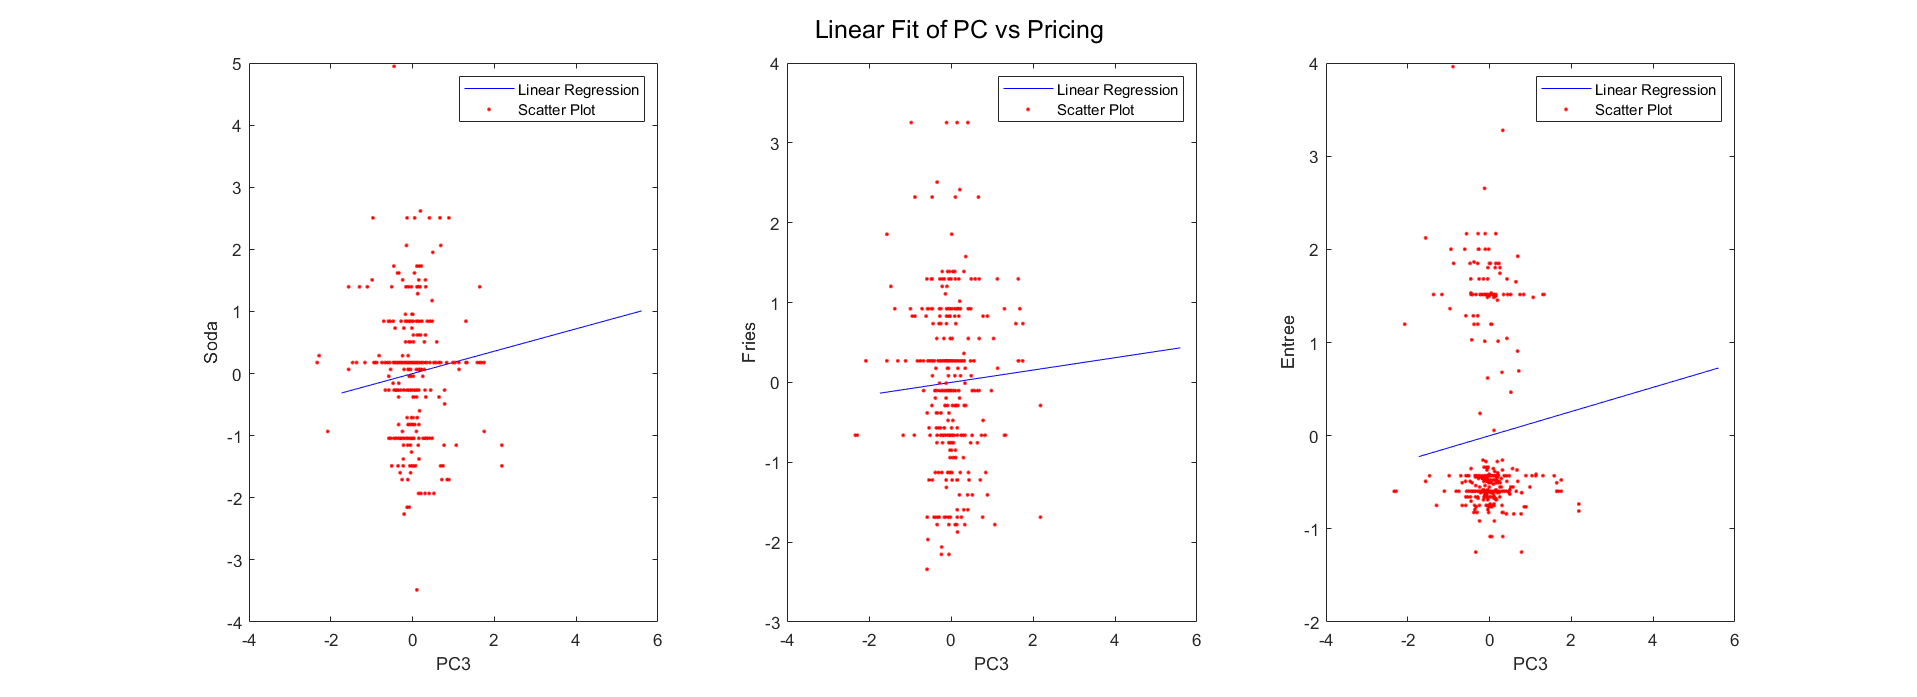

% Plotting PC3 against pricing:
clf; figure();
figure_1 = figure('Position', [100, 100, 2200, 800]);
X = [ones(length(Price_array(:,1)),1) PComp(:,3)];
for n = 1:length(Price_array(1,:))
    subplot(1,3,n)
    line_reg(n) = crossval('mse',X,Price_array(:,n),'Predfun',@regf);
    plot(PComp(:,3),PComp(:,3)*regress(PComp(:,3),Price_array(:,n)), ...
        'b-',PComp(:,1),Price_array(:,n),'r.')
    legend('Linear Regression','Scatter Plot')
    xlabel('PC3'), ylabel(Price_label(n))
end
sgtitle('Linear Fit of PC vs Pricing')

fprintf('The mean crossval scores are %f, %f, and %f.', ...
    line_reg)

The mean crossval scores are 0.983460, 1.004867, and 0.995171.

# Results

Taking into account of all principal components, it seems like there is a discriminatory pricing given our discriminatory category. The linear regression is mostly positive, which means that the pricing goes up as our discriminatory category goes up. For example, as the fraction of black people increases in an area, chances are the prices will also go up in that same area.

# What to Present?

How do we present this finding if we were to present it?

First thing to do is to introduce ourselves and our ideas. We can start our presentation by using a story that connects to the idea and how it is relevant. Such story might be that any of us lives in an area that has a different pricing than other areas. We then introduce our hypothesis. In this case, our hypothesis was that there are no discriminatory pricing.

Without going deep into it, we can touch on the techniques we used for our analysis. For example, we can say that we used PCA to find correlations between the discriminatory category and the pricing and why PCA is used for this findings. We can use the graphs in this lab and explain what they show us and how PCA can or did play a part in it.

After we touch on our techniques, we can conclude with our results. We can explain our graphs and findings and how they make or break our hypothesis. The most important part, in my opinion, is what we can do knowing our result. If we find that there is discrimination in pricing, we can either gather more data or act on it. If there isn't, we can plan on what we can do from here on.